clc
clear
close all

## MNT756: Molecular Modeling - HW 1

## INPUTS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Rbox = 1; % circular boundary
mass = ; % mass of the particle
deltat = 0.001; % time step

% the wall potential is harmonic U = 0.5*kwall*(r-rcut)^2
rcut = 0.05;
kwall = 1000;

% random initial conditions
r0 = Rbox*(rand(1,2)-1);
v0 = rand(1,2)-1;

plotfly = 'yes';
freqplot = 100; % output plot frequency

nsteps = 4e4; % number of steps
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 1. initialize positions, velocities, and potential energy

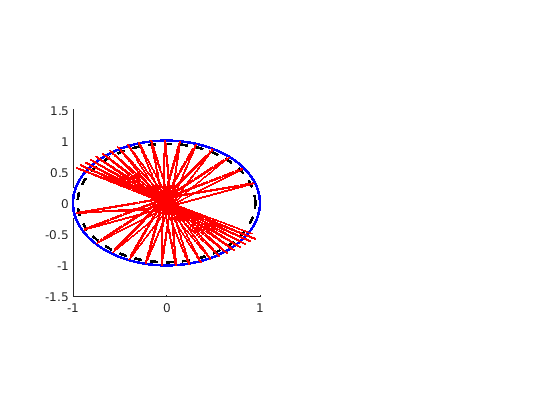

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
r = zeros(nsteps,2);
v = zeros(nsteps,2);
u = zeros(nsteps,1);

% initial conditions
r(1,:) = r0;
v(1,:) = v0;

% calculate potential energy initial configuration
rho = sqrt(sum(r(1,:).^2));
if rho>Rbox-rcut
    u(1) = 0.5*kwall*(rho-(Rbox-rcut))^2;
else
    u(1) = 0;
end

% simulation
for ii=1:nsteps-1
    
    rho = sqrt(sum(r(ii,:).^2));
    
    % 2. calculate forces by the walls on the particles
    if rho>Rbox-rcut % right wall
        F = -kwall*abs((rho-(Rbox-rcut)));
        u(ii+1) = 0.5*kwall*(rho-(Rbox-rcut))^2;
    else
        F = 0;
        u(ii+1) = 0;
    end
    
    % 2.2. calculate the force components and acceleration
    if rho==0
        f = 0; % avoid singularity in the acceleration
    else
        f = F/rho*r(ii,:);
    end
    a = f/mass;
    
    
    % 3. integrate the equations of motion using simple algorithm - 1 order
    % Taylor expansion
    
    r(ii+1,:) = r(ii,:) + v(ii,:)*deltat;
    v(ii+1,:) = v(ii,:) + a*deltat;
   
   
    % 4. output results
    if strcmp(plotfly,'yes')
        if mod(ii,freqplot)==0
            
            subplot(1,2,1)
            viscircles([0 0],Rbox,'Color','b'); hold on;
            viscircles([0 0],Rbox-rcut,'Color','k','LineStyle','--');
            plot(r(1:ii,1),r(1:ii,2),'-r','LineWidth',2);
            axis square
            drawnow
        end
    end
end

## Qusestion 1 to 4 %%%%

New simulation %%% 

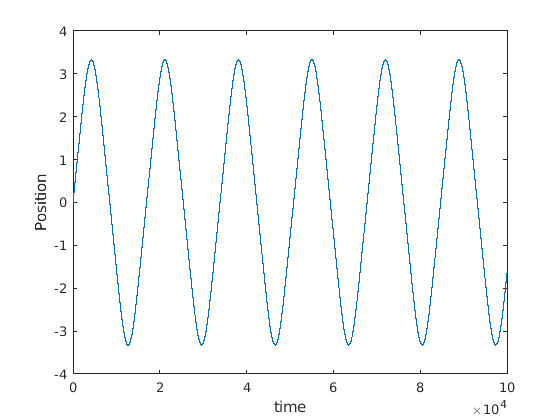

    % Set configuration parameters
    mass = 2;           % Particle mass
    dt = 0.0001;        % Integration time
    dt2 = dt*dt;        % Integration time, squared
    dwPar = 1;          % A parameter to scale the double well potential

    % Set simulation parameters
    nSteps = 100000;    % Total simulation time (in integration steps)
    sampleFreq = 1;     % Sampling frequency
    sampleCounter = 1;  % Sampling counter

    % Set trajectories to follow particle's position and velocity
    xTraj = zeros(1,nSteps/sampleFreq);
    vTraj = zeros(1,nSteps/sampleFreq);
	fTraj = zeros(1,nSteps/sampleFreq);
	
    % Set configuration parameters
    mass = 2;           % Particle mass
    dt = 0.0001;        % Integration time
    dt2 = dt*dt;        % Integration time, squared
    dwPar = 1;          % A parameter to scale the double well potential

    % Set simulation parameters
    nSteps = 100000;    % Total simulation time (in integration steps)
    sampleFreq = 1;     % Sampling frequency
    sampleCounter = 1;  % Sampling counter
	% Set trajectories to use later for Semi-Euler integration for 6.
	x2Traj = zeros(1,nSteps/sampleFreq); 
	v2Traj = zeros(1,nSteps/sampleFreq);
	f2Traj = zeros(1,nSteps/sampleFreq);

    % Set initial conditions
    x = 0;              % Initial position
    oldX = -0.001;      % Position in previous time step'
	v = 0;				% Initial velocity
	oldV = v0;			% Position in previous time step

    % ===================
    % Molecular Dynamics
    % ===================
    for step = 1:nSteps

        % Tmp will hold x(t)
        tmp = x;

        % Calculate the new x position by integrating the equations of motion
        % x(t+dt) = 2*x(t) - x(t-dt) + dt^2*(f(t)/m) + O(dt^4)
        x = 2.0*x - oldX + (-1)*dwPar*4*x.*(x.^2-1)*dt2/mass;
	
		
        % oldX now holds x(t), and x holds x(t+dt)
        oldX = tmp;
		
		% oldV for later use
		tmp = v;

        % Integrate the velocity as well.
        % O(dt) accurate. See Verlet integration on wikipedia
        % v(t+dt) = (x(t+dt) - x(t))/ dt + O(dt)
        v = (x - oldX)/dt;
		
		% oldV now holds v(t), and v holds v(t+dt) 
		oldV = tmp; 
		
		% compute new force
		force = mass * (v - oldV)/dt;

        % Sample
        if mod(step,sampleFreq) == 0
            xTraj(sampleCounter) = x;
            vTraj(sampleCounter) = v;
			fTraj(sampleCounter) = force; 
            sampleCounter = sampleCounter + 1;
        end

    end

    % ===================
    % Simulation results
    % ===================

    % Plot the particle's position trajectory
    figure(2)
    plot(xTraj);
    xlabel('time')
    ylabel('Position')

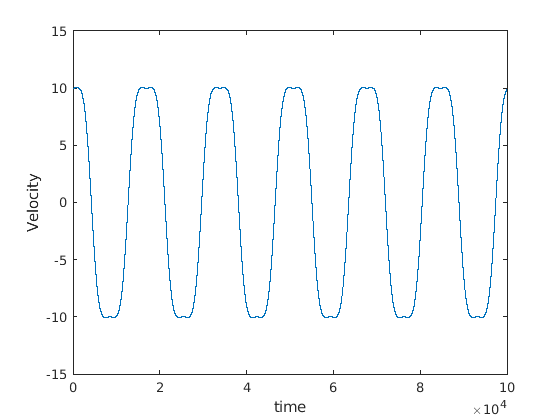

	
	% Plot the particle's velocity 
	figure(3)
	plot(vTraj);
	xlabel('time')
	ylabel('Velocity')

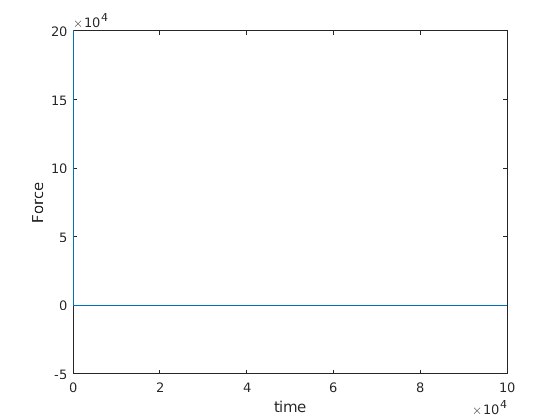

	
	% Plot the force on the particle
	figure(4)
	plot(fTraj);
	xlabel('time')
	ylabel('Force')

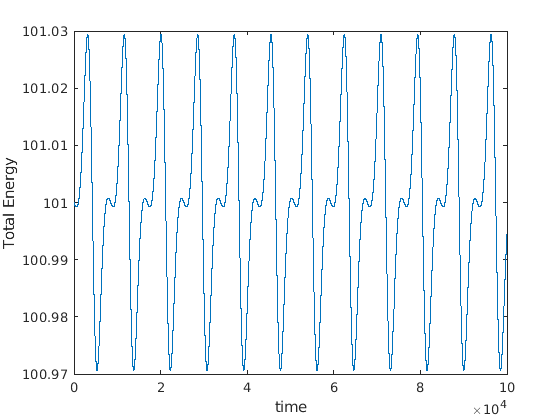


    % Plot the sum of kinetic and potential energy - to check for conservation
    figure(5)
    potEnergy = dwPar*(xTraj.^2-1).^2;
    kinEnergy = 0.5*mass*(vTraj.^2);
    plot(potEnergy + kinEnergy);
    xlabel('time')
    ylabel('Total Energy')

## Question 5. exploring different values for Harmonic Potential, Mass, and Cutoff-Distance %

I used different values for these to observe effects, setting mass size to 12 an nstep of 100000 % 

## 5. exploring different values for Harmonic Potential, Mass, and Cutoff-Distance %%%

## trying different values for these to observe effects %%%

## New simulation %%%

Set configuration parameters

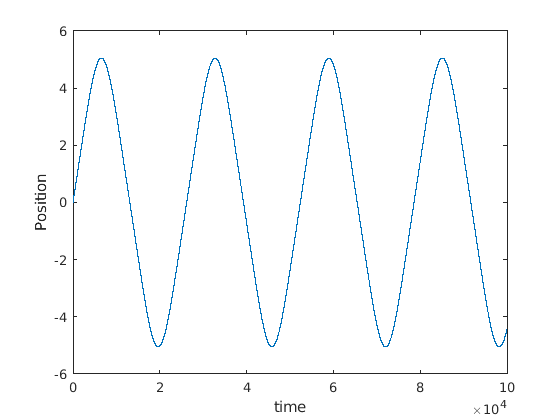

    mass = 12;          % Twelve times the initial particle mass
	rcut = 0.1;		    % increased cut-off for interaction to 0.1 from 0.05
	kwall = 2000;       % doubled harmonic spring potential
	
    dt = 0.0001;        % Integration time
    dt2 = dt*dt;        % Integration time, squared
    dwPar = 1;          % A parameter to scale the double well potential

    % Set simulation parameters
    nSteps = 100000;    % Total simulation time (in integration steps)
    sampleFreq = 1;     % Sampling frequency
    sampleCounter = 1;  % Sampling counter

    % Set trajectories to follow particle's position and velocity
    xTraj = zeros(1,nSteps/sampleFreq);
    vTraj = zeros(1,nSteps/sampleFreq);
	fTraj = zeros(1,nSteps/sampleFreq);
	
	% Set trajectories to use later for Semi-Euler integration for 6.
	x2Traj = zeros(1,nSteps/sampleFreq);
	v2Traj = zeros(1,nSteps/sampleFreq);
	f2Traj = zeros(1,nSteps/sampleFreq);

    % Set initial conditions
    x = 0;              % Initial position
    oldX = -0.001;      % Position in previous time step'
	v = 0;				% Initial velocity
	oldV = v0;			% Position in previous time step

    % ===================
    % Molecular Dynamics
    % ===================
    for step = 1:nSteps

        % Tmp will hold x(t)
        tmp = x;

        % Calculate the new x position by integrating the equations of motion
        % x(t+dt) = 2*x(t) - x(t-dt) + dt^2*(f(t)/m) + O(dt^4)
        x = 2.0*x - oldX + (-1)*dwPar*4*x.*(x.^2-1)*dt2/mass;
	
        % oldX now holds x(t), and x holds x(t+dt)
        oldX = tmp;
		
		% oldV for later use
		tmp = v;

        % Integrate the velocity as well.
        % O(dt) accurate. See Verlet integration on wikipedia
        % v(t+dt) = (x(t+dt) - x(t))/ dt + O(dt)
        v = (x - oldX)/dt;
		
		% oldV now holds v(t), and v holds v(t+dt) 
		oldV = tmp; 
		
		% compute new force
		force = mass * (v - oldV)/dt;

        % Sample
        if mod(step,sampleFreq) == 0
            xTraj(sampleCounter) = x;
            vTraj(sampleCounter) = v;
			fTraj(sampleCounter) = force; 
            sampleCounter = sampleCounter + 1;
        end

    end

    % ===================
    % Simulation results
    % ===================

    % Plot the particle's position trajectory
    figure(6)
    plot(xTraj);
    xlabel('time')
    ylabel('Position')

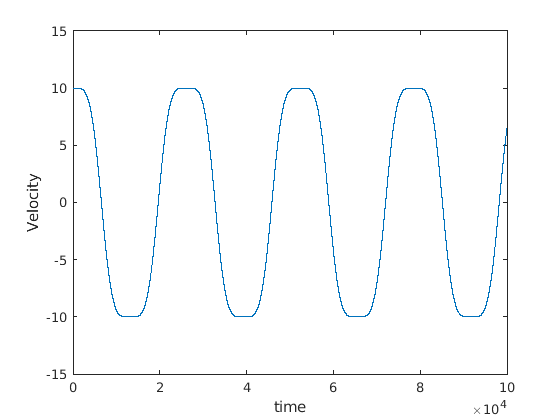

	
	% Plot the particle's velocity 
	figure(7)
	plot(vTraj);
	xlabel('time')
	ylabel('Velocity')

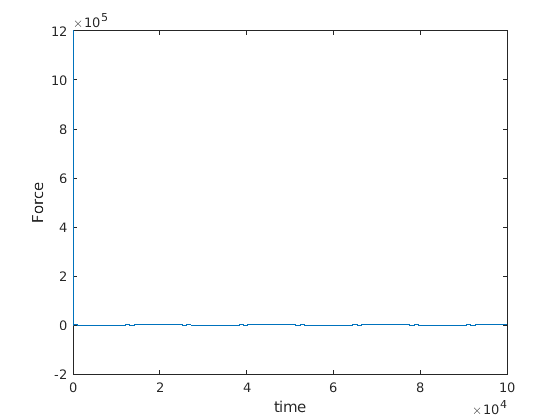

	
	% Plot the force on the particle
	figure(8)
	plot(fTraj);
	xlabel('time')
	ylabel('Force')

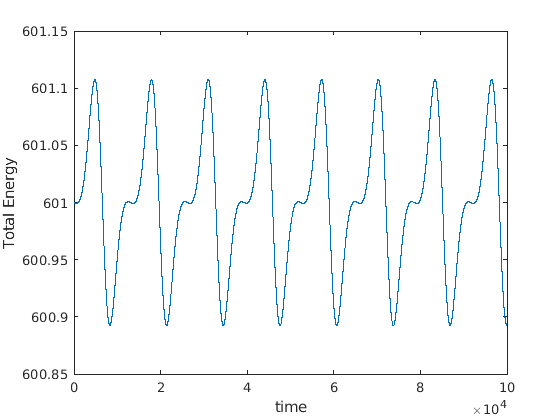


    % Plot the sum of kinetic and potential energy - to check for conservation
    figure(9)
    potEnergy = dwPar*(xTraj.^2-1).^2;
    kinEnergy = 0.5*mass*(vTraj.^2);
    plot(potEnergy + kinEnergy);
    xlabel('time')
    ylabel('Total Energy')

## 6. Using alternative integration method for Newton's Law of motion in Matlab

Integration of Euler method initial set up

h=0.5

h = 0.5000

x=0:h:4;
y=zeros(size(x));
y(1)=1;
n=numel(y);

for i = 1:n-1
dydx= -2*x(i).^3 +12*x(i)^2 -20*x(i)+8.5
y(i+1) =y(i)+dydx*h; % Euler integration

% fprintf('="Y"\n\t') %0.01f', y(i));
end

dydx = 8.5000

dydx = 1.2500

dydx = -1.5000

dydx = -1.2500

dydx = 0.5000

dydx = 2.2500

dydx = 2.5000

dydx = -0.2500

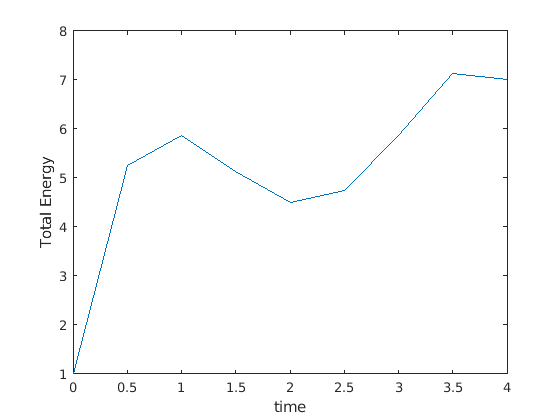

plot(x,y);
 xlabel('time')
 ylabel('Total Energy')

% Plot the particle's position trajectory